# Demonstration of Feature Selection Functions in scGEApp

## HVG analysis with single data X

cdgea; % set working directory
[X,genelist]=sc_readfile('example_data/GSM3044891_GeneExp.UMIs.10X1.txt');   

Reading example_data/GSM3044891_GeneExp.UMIs.10X1.txt ...... done.


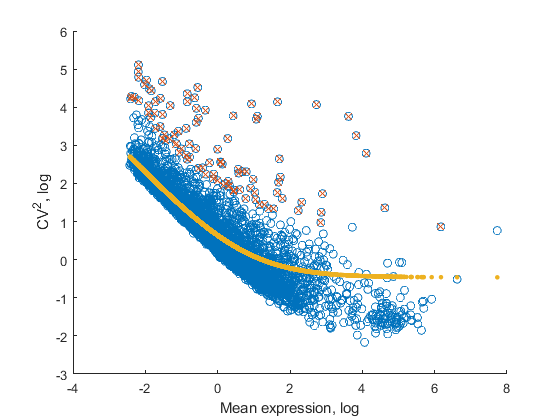

[X,genelist]=sc_selectg(X,genelist,3,1);
% Normalize data with DESeq method
Xn=sc_norm(X,'type','deseq');
[T]=sc_hvg(Xn,genelist,true,true);


% Highly variable genes (HVGenes), FDR<0.05
HVGenes=T.genes(T.fdr<0.05)

HVGenes = 1227×1 string array
    "BCL2A1"
    "CYP1B1"
    "TXNIP"
    "RSPH1"
    "RP11-856M7.6"
    "BRD3"
    "HIST2H2AA3"
    "JCHAIN"
    "LMNA"
    "MACROD2"
    "MIR3142HG"
    "PEG10"
    "CCL22"
    "PRKCDBP"
    "IGKV1-12"
    "IGHA2"
    "CDKN1A"
    "S100A4"
    "PDLIM4"
    "MIER2"
    "CRIP1"
    "IGLV6-57"
    "WFDC2"
    "C10orf10"
    "VIM"
    "GNG8"
    "CD69"
    "HSPA1B"
    "HSPB1"
    "FAM43A"
    "HMOX1"
    "IGKC"
    "MAL"
    "CKB"
    "FSCN1"
    "RGS1"
    "RGS2"
    "PTP4A3"
    "CCL3L3"
    "HIST1H1D"
    "HIST1H1C"
    "TVP23A"
    "CXCL10"
    "TNFRSF4"
    "CTSC"
    "CXCL8"
    "UBE2C"
    "BIRC3"
    "NFKBIA"
    "HIST1H2BC"
    "HIST1H2BJ"
    "TNFAIP2"
    "CCL17"
    "MIR155HG"
    "SFN"
    "CCL4L2"
    "UBD"
    "TNFRSF18"
    "RRM2"
    "CREB3L1"
    "SSTR2"
    "AICDA"
    "ATP1B1"
    "TUBB2A"
    "TUBB2B"
    "CCR7"
    "CD83"
    "NFATC1"
    "ID2"
    "ID3"
    "BIN1"
    "FXYD6-FXYD2"
    "PIF1"
    "CCL3"
    "CCL4"
    "RP5-887A10.1"
 

## Spline-fit feature selection with single data X

[X,genelist]=sc_readfile('example_data/GSM3044891_GeneExp.UMIs.10X1.txt');   

Reading example_data/GSM3044891_GeneExp.UMIs.10X1.txt ...... done.


[X,genelist]=sc_selectg(X,genelist,3,1);

sortit=true;
[T1]=sc_splinefit(X,genelist,sortit);
% Top 50 featured genes with highest deviation (D) values 
T1.genes(1:50)

ans = 50×1 string array
    "IGLC2"
    "IGHG1"
    "IGKC"
    "IGHG3"
    "CCL22"
    "IGHM"
    "IGHG4"
    "WFDC2"
    "IGKV1-12"
    "CCL4"
    "IGLC3"
    "CCL3L3"
    "FXYD2"
    "PRKCDBP"
    "RGS1"
    "IFI27"
    "CCL3"
    "TMSB4X"
    "FXYD6-FXYD2"
    "UBD"
    "CKB"
    "CCL4L2"
    "HIST2H2AA3"
    "RARRES2"
    "KCNMA1"
    "CYP1B1"
    "HIST1H1C"
    "FSCN1"
    "LTA"
    "IL32"
    "LMNA"
    "CCL17"
    "IER3"
    "MIR155HG"
    "CCR7"
    "CXCL10"
    "HIST1H2BJ"
    "CXCL8"
    "TNFRSF18"
    "IGHA1"
    "MIR3142HG"
    "JCHAIN"
    "PEG10"
    "CRIP1"
    "TVP23A"
    "IGHV1-24"
    "DUSP2"
    "SFN"
    "UBE2C"
    "NFKBIA"


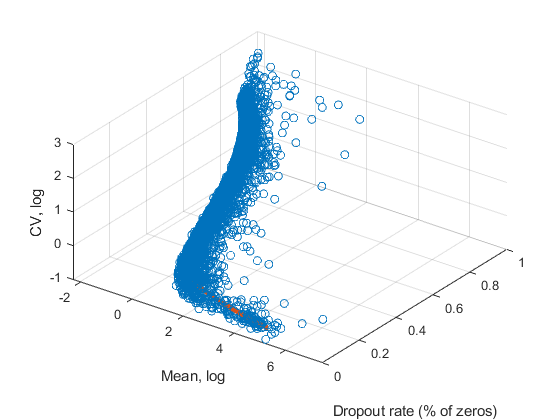

dofit=true;
showdata=true;
% Show data points and the spline-fit curve
figure;
sc_scatter3(X,genelist,dofit,showdata);
view([36.39 46.25])

## Analysis of differentially deviated (DD) genes using spline-fit feature selection with data X and Y

Read and pre-process two data sets, X and Y

[X,genelistx]=sc_readfile('example_data/GSM3204304_P_P_Expr_999cells.csv');

Reading example_data/GSM3204304_P_P_Expr_999cells.csv ...... done.


[Y,genelisty]=sc_readfile('example_data/GSM3204305_P_N_Expr_999cells.csv');

Reading example_data/GSM3204305_P_N_Expr_999cells.csv ...... done.


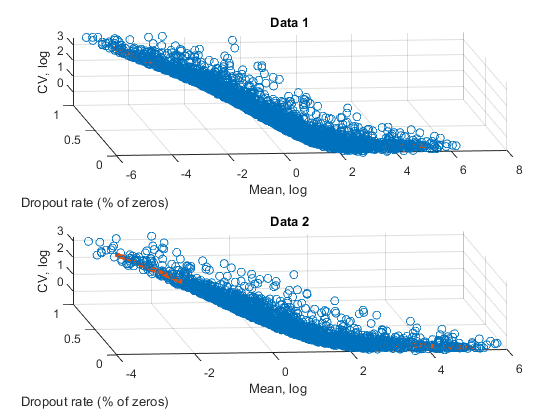

[X,genelistx]=sc_selectg(X,genelistx,3,1);
[Y,genelisty]=sc_selectg(Y,genelisty,3,1);

% Show 3D scatter plot and spline-fit curve for X
figure;
dofit=true;
showdata=true;
subplot(2,1,1)
sc_scatter3(X,genelistx,dofit,showdata);
title('Data 1')
view([-6.39 36.70])

% Show 3D scatter plot and spline-fit curve for Y
%figure;
subplot(2,1,2)
sc_scatter3(Y,genelisty,dofit,showdata);
title('Data 2')
% view([24.08 32.68])
view([-6.39 36.70])

## Using function SC_SPLINEFIT2 to fit X and Y separately and obtain DD

value for each gene.

[T2]=sc_splinefit2(X,Y,genelistx,genelisty,true);

## Top 50 genes with highest DD value.

T2.genes(1:50)

ans = 50×1 string array
    "TSLP"
    "ID4"
    "AKR1B10"
    "WFDC2"
    "SCGB1A1"
    "S100P"
    "H1F0"
    "CHI3L2"
    "NUPR1"
    "MSMB"
    "CSTB"
    "RP11-338I21.1"
    "TNFAIP2"
    "SLPI"
    "DUOXA2"
    "RARRES1"
    "DKK1"
    "HIST1H2AC"
    "CA2"
    "CENPE"
    "TGM1"
    "DDIT3"
    "CCNB1"
    "LAYN"
    "IDO1"
    "FTL"
    "SPRR2A"
    "SFTA1P"
    "SAA2"
    "GNE"
    "CCNE1"
    "CCND1"
    "CLN3"
    "NMB"
    "NUF2"
    "TRIP13"
    "S100A9"
    "CENPF"
    "MDK"
    "KRT6B"
    "SERPINB1"
    "ELF3"
    "BRCA2"
    "MARCKSL1"
    "IFNB1"
    "HIST1H4H"
    "BTG1"
    "KLK10"
    "CLEC2D"
    "MASTL"


## Run GSEAPreranked App with genes ranked with DD

addpath('thirdparty/GSEA');
a=gseapr;
a.load_data(T2);

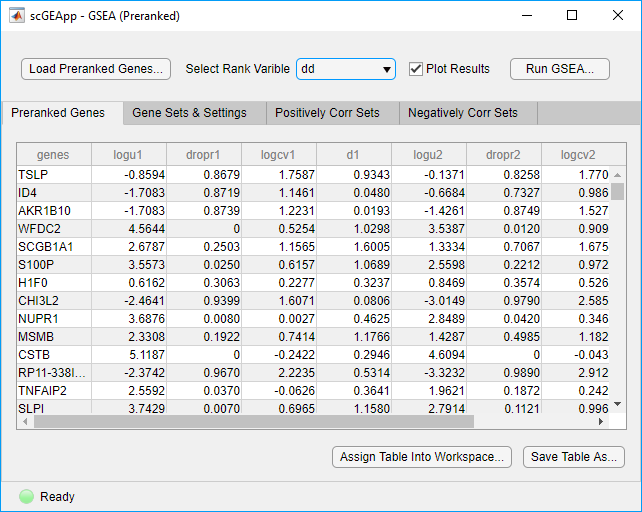

## Click gene set names in GSEA result table to show GSEA plots

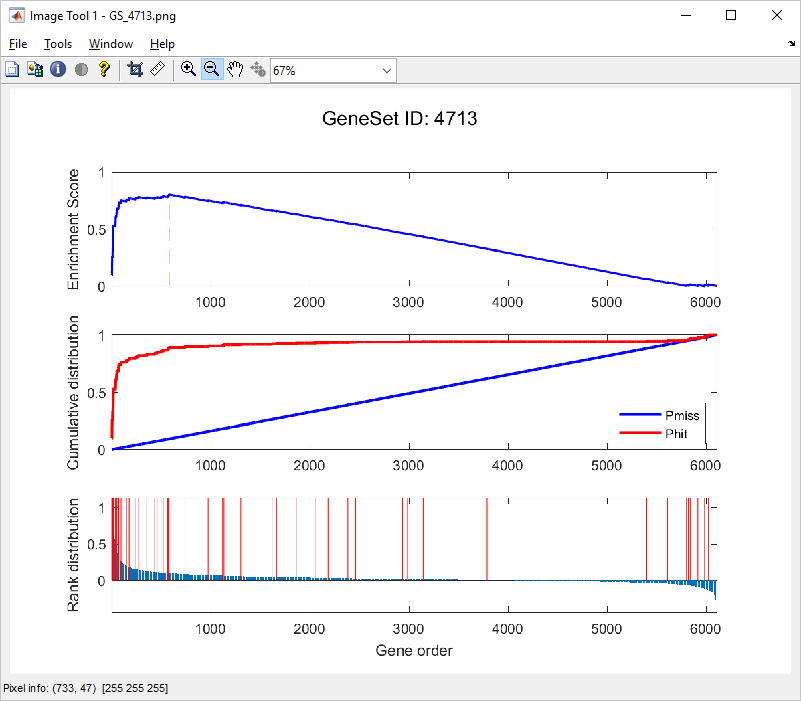

## The End